FIltro pasa bajos

De 6to orden topologia Butterworth, Fc = 300 y Fs = 1000 Hz (corresponde a 0.6$\pi$rad/sample)

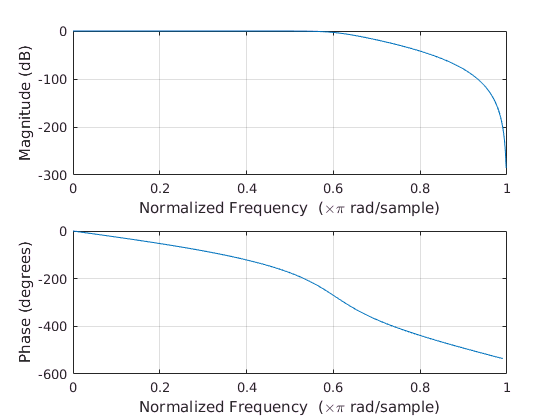

fc = 300; 
fs = 1000;

[b,a] = butter(6,fc/(fs/2)); % orden, frecuencia de corte normalizada
freqz(b,a)

dataIn = randn(1000,1);
dataOut = filter(b,a,dataIn); % para aplicar el filtro
subplot(2,1,1)

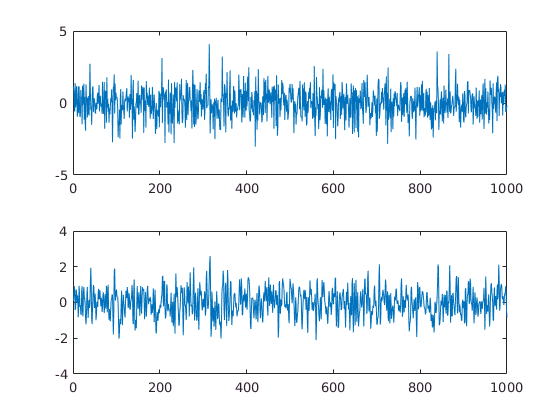

plot(dataIn)
subplot(2,1,2)
plot(dataOut)

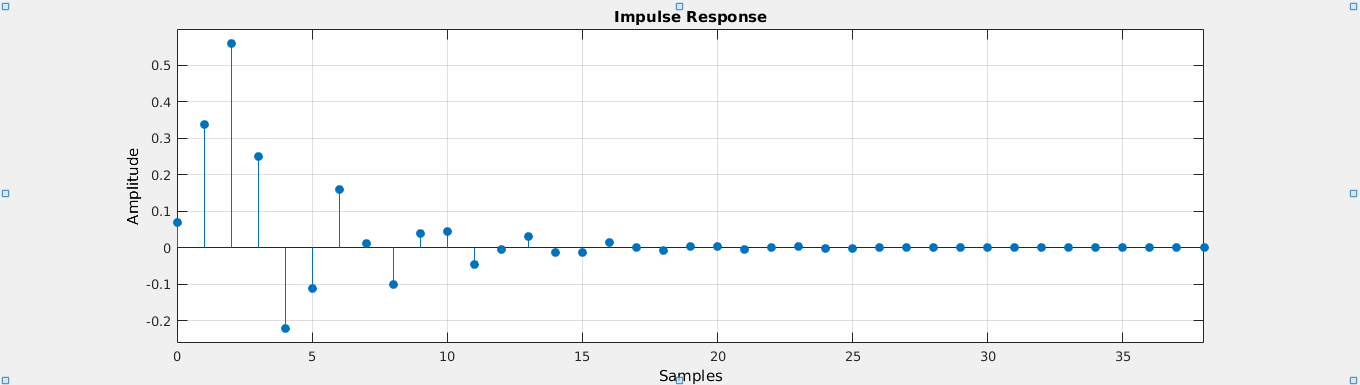


fvtool(b,a)

FIltro elimina banda

De 10mo orden topologia Butterworth, Finf = 300, Fsup= 3000 y Fs = 10000 Hz (corresponde a 0.6$\pi$rad/sample)

finf = 3000; 
fsup = 4000;
fs = 20000;

[b,a] = butter(6,[finf/(fs/2) fsup/(fs/2)],'stop'); % orden, frecuencia de corte normalizada
freqz(b,a)

dataIn = randn(1000,1);
dataOut = filter(b,a,dataIn); % para aplicar el filtro
subplot(2,1,1)
plot(dataIn)
subplot(2,1,2)
plot(dataOut)

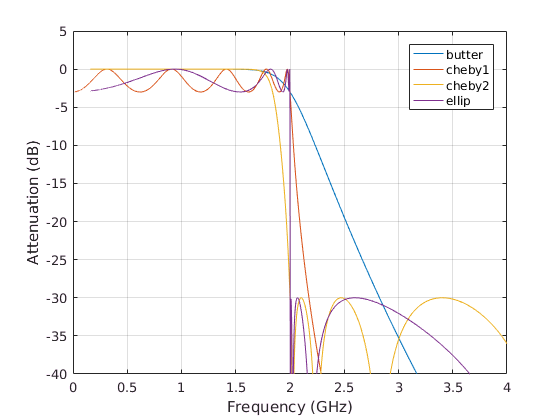

n = 10;
f = 2e9;

[zb,pb,kb] = butter(n,2*pi*f,'s');
[bb,ab] = zp2tf(zb,pb,kb);
[hb,wb] = freqs(bb,ab,4096);

[z1,p1,k1] = cheby1(n,3,2*pi*f,'s');
[b1,a1] = zp2tf(z1,p1,k1);
[h1,w1] = freqs(b1,a1,4096);

[z2,p2,k2] = cheby2(n,30,2*pi*f,'s');
[b2,a2] = zp2tf(z2,p2,k2);
[h2,w2] = freqs(b2,a2,4096);

[ze,pe,ke] = ellip(n,3,30,2*pi*f,'s');
[be,ae] = zp2tf(ze,pe,ke);
[he,we] = freqs(be,ae,4096);

clf
plot(wb/(f*pi),mag2db(abs(hb)))
hold on
plot(w1/(f*pi),mag2db(abs(h1)))
plot(w2/(f*pi),mag2db(abs(h2)))
plot(we/(f*pi),mag2db(abs(he)))
axis([0 4 -40 5])
grid
xlabel('Frequency (GHz)')
ylabel('Attenuation (dB)')
legend('butter','cheby1','cheby2','ellip')
hold off